# Three-Signal Models

clear; IntializeNotebook(Quiet=true);

## Styles

% Styles relevant for the notebook (live script) itself; not
% relevant for actual plots, so not essential
% SetStyles();

% Next styles used in plots, so useful even in standard scripts
% Define these as globals so that local functions can reference
% them if needed.

global FontName;
FontName   = "Arial"; % "Lucida Sans OT"

global C4Color C12Color MixedColor LasBColor LasIColor RhlIColor;
C4Color    = [237,176,129]/255;
C12Color   = [193,65,104]/255;
MixedColor = [229,113,94]/255;
LasBColor  = [44,49,114]/255;
LasIColor  = [165,205,144]/255;
RhlIColor  = [52,133,141]/255;

% Custom color maps
global crest flare;
load("crest.mat");
load("flare.mat");

## Setup

% This notebook analyzes a *hypothetical* QS architecture of the three
% canonical P. aeruginosa QS systems: las, rhl, and pqs. It incorporates
% data on the observed relationships between las and rhl, but the
% considered relationships between those systems and pqs are purely
% speculative. The high-level interactions, however, are based on 
% published literature (Lee and Zhang, 2014).
%
%     las → pqs
%     pqs → rhl
%     rhl ⸡ pqs
%
% The magnitudes of the interactions with pqs and pqs parameters are
% speculative. In addition, the synergistic effects of las and rhl
% combined are neglected to simplify the analysis.
%
% Using the indices 1 (las), 2 (rhl), and 3 (pqs):
%
% E1 = a10 + a11 S1/(S1 + K11) + a12 S2/(S2 + K12) + a13 S3/(S3 + K13)
% E2 = a20 + a21 S1/(S1 + K21) + a22 S2/(S2 + K22) + a23 S3/(S3 + K23)
% E3 = a30 + a31 S1/(S1 + K31) + a32 S2/(S2 + K32) + a33 S3/(S3 + K33)

E1 = @(S, p) ...
    p.a10 + ...
    p.a11 / (1 + p.K11 / S(1)) + ...
    p.a12 / (1 + p.K12 / S(2)) + ...
    p.a13 / (1 + p.K13 / S(3));
E2 = @(S, p) ...
    p.a20 + ...
    p.a21 / (1 + p.K21 / S(1)) + ...
    p.a22 / (1 + p.K22 / S(2)) + ...
    p.a23 / (1 + p.K23 / S(3));
E3 = @(S, p) ...
    p.a30 + ...
    p.a31 / (1 + p.K31 / S(1)) + ...
    p.a32 / (1 + p.K32 / S(2)) + ...
    p.a33 / (1 + p.K33 / S(3));

% To explore the effect of population density, use a dynamic model for
% signal concentration
%
% dS1/dt = c1 E1(S) N - d1 S1
% dS2/dt = c2 E2(S) N - d2 S2
% dS3/dt = c3 E3(S) N - d3 S3
%
% non-dimensionalized by setting d2 = 1;

dSdt = @(S, N, p) [ ...
    p.c1 * E1(S, p) * N - p.d1 * S(1), ...
    p.c2 * E2(S, p) * N - p.d2 * S(2), ...
    p.c3 * E3(S, p) * N - p.d3 * S(3)  ...
];

% From data:

params = struct;
params.a10 = 1670;
params.a11 = 61000;
params.K11 = 0.24;
params.a12 = 9000;
params.K12 = 1;
params.a20 = 1861;
params.a21 = 63000;
params.K21 = 0.052;
params.a22 = 10000;
params.K22 = 1.6;

params.c1 = 1.3e-05;
params.c2 = 2.5e-05;
params.d1 = 1.7;
params.d2 = 1;

## Interactive Visualization

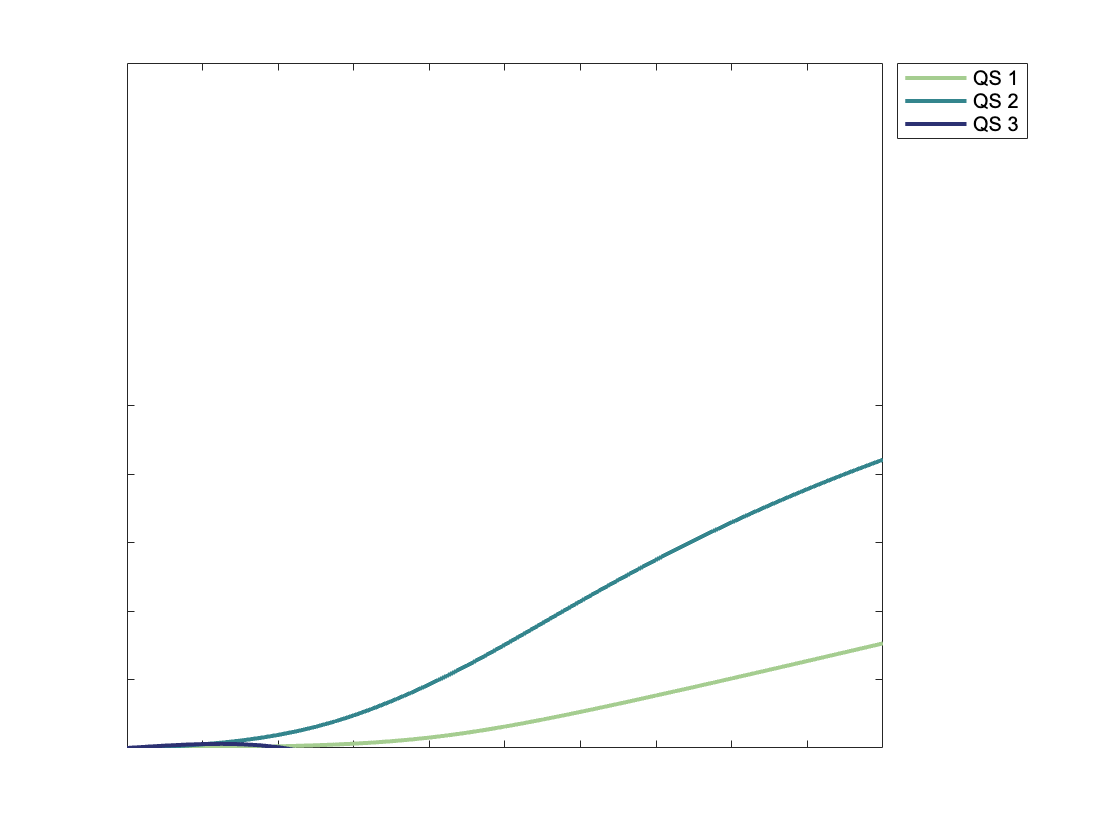

%log10(min([params.a10, params.a20]))
%log10(max([params.a10, params.a20]))
%log10(min([params.a11, params.a22]))
%log10(min([params.a11, params.a22]))
%log10(min([params.a12, params.a21]))
%log10(max([params.a12, params.a21]))
%log10(min([params.K11, params.K22]))
%log10(max([params.K11, params.K22]))
%log10(min([params.K12, params.K21]))
%log10(max([params.K12, params.K21]))

% Common options for the solver
SolveOptions = optimoptions('fsolve', 'Display', 'none');
N = 0 : 0.025 : 1.0;
S0 = [1, 1, 0];
Sstar = zeros(length(N), 3);
figure;

params.c3 = (params.c1 + params.c2) / 2;
params.d3 = (params.d1 + params.d2) / 2;
params.a13 = 0; params.K13 = 0.5;
params.a30 = 10^(4);
params.a33 = 10^(4);
params.a31 = 10^(5.8);
params.a32 = -1 * 10^(6.2);
params.a23 = 10^(4);
params.K33 = 10^(0);
params.K31 = 10^(-0.5);
params.K32 = 10^(0.5);
params.K23 = 10^(-0.5);

for Nidx = 1: length(N)
    dS = @(S) dSdt(S, N(Nidx), params);
    S0 = fsolve(dS, S0, SolveOptions);
    Sstar(Nidx, :) = S0;
end
PlotExpression( N=N, Sstar=Sstar, Legend=true)

## Visualize Alternatives

% Values common to all examples
params.c3 = (params.c1 + params.c2) / 2;
params.d3 = (params.d1 + params.d2) / 2;
params.a13 = 0; 
params.K13 = 0.5;

params.a30 = 10^4;
params.a33 = 10^4;
params.a23 = 10^4;
params.K33 = 10^0;
params.K23 = 10^(-0.5);

% Common options for the solver
SolveOptions = optimoptions('fsolve', 'Display', 'none');
N = 0 : 0.025 : 1.0;

% Case 1: Minimal activation
params.a31 = 10^4;
params.a32 = -1 * 10^4;
params.K31 = 10^(-0.5);
params.K32 = 10^(-0.5);

S0 = [1, 1, 0];
Sstar = zeros(length(N), 3);
for Nidx = 1: length(N)
    dS = @(S) dSdt(S, N(Nidx), params);
    S0 = fsolve(dS, S0, SolveOptions);
    Sstar(Nidx, :) = S0;
end
Sstar1 = Sstar;

% Case 2: Strong activation
params.a31 = 10^6;
params.a32 = -1 * 10^4;
params.K31 = 10^(-0.5);
params.K32 = 10^(-0.5);

S0 = [1, 1, 0];
Sstar = zeros(length(N), 3);
for Nidx = 1: length(N)
    dS = @(S) dSdt(S, N(Nidx), params);
    S0 = fsolve(dS, S0, SolveOptions);
    Sstar(Nidx, :) = S0;
end
Sstar2 = Sstar;

% Case 3: Limiting
params.a31 = 10^5.2;
params.a32 = -1 * 10^5.5;
params.K31 = 10^(-1.5);
params.K32 = 10^(0.6);

S0 = [1, 1, 0];
Sstar = zeros(length(N), 3);
for Nidx = 1: length(N)
    dS = @(S) dSdt(S, N(Nidx), params);
    S0 = fsolve(dS, S0, SolveOptions);
    Sstar(Nidx, :) = S0;
end
Sstar3 = Sstar;

% Case 4: Damping
params.a31 = 10^5.8;
params.a32 = -1 * 10^6.2;
params.K31 = 10^(-1.5);
params.K32 = 10^(0.5);

S0 = [1, 1, 0];
Sstar = zeros(length(N), 3);
for Nidx = 1: length(N)
    dS = @(S) dSdt(S, N(Nidx), params);
    S0 = fsolve(dS, S0, SolveOptions);
    Sstar(Nidx, :) = S0;
end
Sstar4 = Sstar;

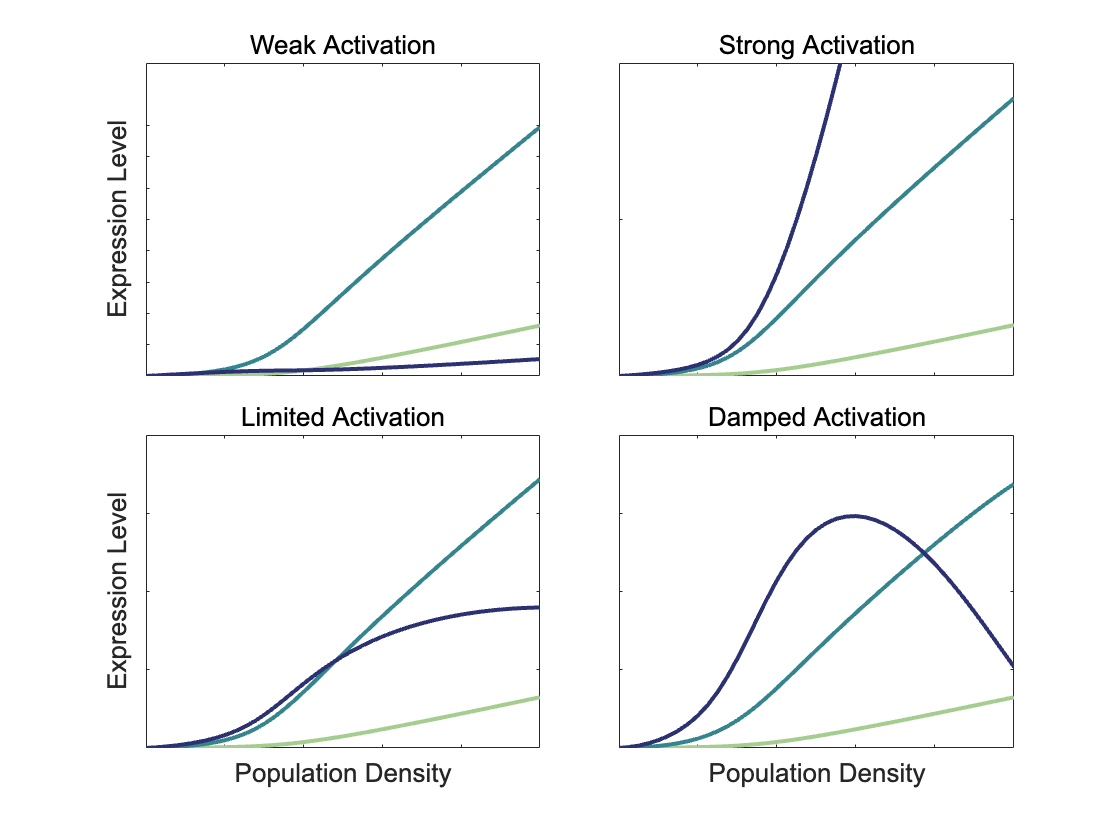


Expression = figure;
tiledlayout(2, 2, TileSpacing="compact");
nexttile;
PlotExpression( ...
    N=N, ...
    Sstar=Sstar1, ...
    Ylabel="Expression Level", ...
    Title="Weak Activation" ...
);
nexttile;
PlotExpression( ...
    N=N, ...
    Sstar=Sstar2, ...
    Title="Strong Activation" ...
);
nexttile;
PlotExpression( ...
    N=N, ...
    Sstar=Sstar3, ...
    Xlabel="Population Density", ...
    Ylabel="Expression Level", ...
    Title="Limited Activation" ...
);
nexttile;
PlotExpression( ...
    N=N, ...
    Sstar=Sstar4, ...
    Xlabel="Population Density", ...
    Title="Damped Activation" ...
);
exportgraphics(Expression, "../Prefigures/three_signals.pdf", 'ContentType', 'vector');

## Local Functions

function IntializeNotebook(Options)
% InitializeNotebook() ensures that the live script notebook is in a known
% starting state. Its intent is to guarantee reproducability of the
% notebook results. Note that the `clear` command does not have full
% effect when implemented within a function. Consequently, the notebook
% should execute that command explicitly before calling this function.
%
% For documentation, this function will, by default, display version and
% platform information within the notebook.
    arguments
        Options.Quiet logical = false; % if true, don't show version info
    end

    % clear workspace elements
    clc; clf;

    % initialize environment
    rng default;  % set random number generator for reproducibility
    
    if ~Options.Quiet
        % show version/platform information
        disp(strcat("This notebook created on ", string(datetime)))
        % suppress needless warning message about product ''
        warning('off', 'MATLAB:ver:NotFound');
            ver '' % don't bother with unused toolboxes, etc.
        warning('on',  'MATLAB:ver:NotFound');
    end

end

function SetStyles() %#ok<DEFNU>
% Set styles such as fonts and colors for notebook.

    Settings = settings;
    Settings.matlab.fonts.editor.normal.Name.TemporaryValue = "Lucida Bright OT";
    Settings.matlab.fonts.editor.title.Name.TemporaryValue = "Lucida Sans OT";
    Settings.matlab.fonts.editor.heading1.Name.TemporaryValue = "Lucida Sans OT";
    Settings.matlab.fonts.editor.heading2.Name.TemporaryValue = "Lucida Sans OT";
    Settings.matlab.fonts.editor.heading3.Name.TemporaryValue = "Lucida Sans OT";
    Settings.matlab.fonts.editor.code.Name.TemporaryValue = "Lucida Console DK";
    Settings.matlab.fonts.codefont.Name.TemporaryValue = "Lucida Console DK";
end

function PlotExpression(Options)
    arguments
        Options.N
        Options.Sstar;
        Options.Xlabel string = "";
        Options.Ylabel string = "";
        Options.Title string = "";
        Options.Subtitle string = "";
        Options.Legend logical = false;
    end

    global LasIColor RhlIColor LasBColor FontName;

    plot(Options.N, Options.Sstar(:,1), LineWidth=2, Color=LasIColor);
    hold on;
    plot(Options.N, Options.Sstar(:,2), LineWidth=2, Color=RhlIColor);
    plot(Options.N, Options.Sstar(:,3), LineWidth=2, Color=LasBColor);
    xticklabels({});
    yticklabels({});
    ylim([0, 2]);
    if Options.Xlabel ~= ""
        xlabel(Options.Xlabel, FontName=FontName, FontSize=13);
    end
    if Options.Ylabel ~= ""
        ylabel(Options.Ylabel, FontName=FontName, FontSize=13);
    end
    if Options.Title ~= ""
        title(Options.Title, FontName=FontName, FontSize=13, FontWeight="normal");
    end
    if Options.Subtitle ~= ""
        text(-0.15, 1.05, Options.Subtitle, FontName=FontName, FontSize=18, FontWeight="normal", Units="normalized");
    end
    if Options.Legend
        legend(["QS 1", "QS 2", "QS 3"], ...
            FontName=FontName, FontSize=10, ...
            Location='northeastoutside' ...
        );
    end
end